## Extraction of the Lookup Table

% Configuration
root = '/Users/hp024/Documents/maelyne/MRI/Diffusion/monte-carlo-simulation-sphere-PGSE-main/data';  
projname = 'AMBER_maelyne';
population_type = 'lognorm';
population_label = [population_type, '_population_RealisticTests2_V3'];
projectpath = fullfile(root, projname, population_label);

lut_file = fullfile(projectpath, 'lookup_table.mat');

% If the look up table already exist in the directory
if isfile(lut_file)
    fprintf('Loading existing lookup table...\n');
    load(lut_file, 'params', 'signals_4D', 'sequence');
else
    fprintf('Lookup table not found. Running generation...\n');
    params_file = fullfile(projectpath, 'params_in.txt');

    if exist(params_file, 'file')
        params_data = readmatrix(params_file);
        Ncombos = size(params_data, 1);
    else
        error('params_in.txt not found in %s', projectpath);
    end

    simdir = fullfile(projectpath, 'sphere_0001'); %if we assume that the b-values and the directions of the gradients are the same for every file sphere_####

    % Load bvecs from gradient_btab.txt
    btab_raw = readmatrix(fullfile(simdir, 'gradient_bvalstab.txt'));
    [C, IA, IC] = unique(btab_raw);
    bval = C/1000;
    n_bvec = IA(2)-IA(1);
    Btab = readmatrix(fullfile(simdir, 'gradient_btab.txt'));
    btab = reshape(Btab, 4, []); %gradient_btab is a vector of size n_bval*n_bvec*4 (at first each line contained one bvalue and one direction) 
    bvecs = btab(2:end,1:n_bvec).';  
    
    % Load diffusion times and pulse widths
    TD = readmatrix(fullfile(simdir, 'TD_array.txt')); 
    pulse_widths = readmatrix(fullfile(simdir, 'gradient_DELdel.txt'));
    pulse_widths = reshape(pulse_widths, 2, []).';
    delta = pulse_widths(:,2);
    
    % Compute derived values  
    n_bval = numel(bval);
    n_del = numel(TD);
    n_signals = n_bvec * n_bval * n_del;
    
    % Initialize sequence struct
    sequence.bval = bval;
    sequence.bvecs = bvecs;
    sequence.n_bval = n_bval;
    sequence.n_bvec = n_bvec;
    sequence.n_del = n_del;
    sequence.TD = TD;
    sequence.delta = delta(1:n_del);  % just in case length mismatch
    
    % Outputs arrays
    params = zeros(Ncombos, 5);     % f, Dex, rmean, rsd, kappa
    signals_4D = zeros(Ncombos, n_del, n_bval, n_bvec);  % [i × d × b × v]
    
    % Loop over simulations
    for i = 1:Ncombos
        simname = sprintf('sphere_%04d', i);
        simdir = fullfile(projectpath, simname);
        
        % --- Load input parameters ---
        % Parameters are saved during CUDA sim:
        % Din, Dex, kappa, initFlag, res (we assume Din = 1 is constant)
        parafile = fullfile(simdir, 'sim_para.txt');
        if ~exist(parafile, 'file')
            warning('Missing sim_para.txt for simulation %d', i);
            continue;
        end
        paravalues = readmatrix(parafile);
        
        Din = paravalues(4); 
        Dex = paravalues(5);
        kappa = paravalues(6);
        
        % --- Load populations parameters ---
        pop_para_file = fullfile(simdir, 'population_para.txt');
        pop_para = readmatrix(pop_para_file);
        rmean = pop_para(1);
        rsd = pop_para(2);
        pop_perc = pop_para(3);
        f = pop_para(4);
        
        % --- Store parameters ---
        params(i,:) = [f, Dex, rmean, rsd, kappa];
        
        % --- Load signals ---
        sigfile = fullfile(simdir, 'sig_diffusion.txt');
        sig = readmatrix(sigfile);  % should be [n_signals × 1]
    
        if numel(sig) ~= n_signals
            warning('Unexpected signal length for simulation %d', i);
            continue;
        end
        
        % in case the signal is negative
        sig(sig < 1e-6) = 1e-3;
        
        % reshape to [nDel × nBval × nBvec]
        sig3D = reshape(sig, [n_bvec, n_bval, n_del]); 
        sig3D = permute(sig3D, [3 2 1]);  % [d × b × v]
    
        % store in 4D array
        signals_4D(i,:,:,:) = sig3D; 
    end
    
    % Save look-up table
    save(fullfile(projectpath, 'lookup_table.mat'), ...
        'params', 'signals_4D', 'sequence');
    
    disp('Lookup table saved successfully.');
    save(lut_file, 'params', 'signals_4D', 'sequence');
end

Loading existing lookup table...


## Check the Lookup Table values

% Displays for verification
bval = sequence.bval;
TD = sequence.TD;
bvecs = sequence.bvecs;

disp('--- b values ---');

--- b values ---


disp(bval);

         0
    0.2500
    0.5000
    0.8000
    1.2000
    1.6000
    2.0000
    3.5000



disp('--- Diffusion times ---');

--- Diffusion times ---


disp(TD);

    15
    45
    75



disp('--- Gradient directions ---');

--- Gradient directions ---


disp(bvecs);

    0.7071         0    0.7071
   -0.7071         0    0.7071
         0    0.7071    0.7071
         0    0.7071   -0.7071
    0.7071    0.7071         0
   -0.7071    0.7071         0




i = 1;
s = squeeze(signals_4D(i,:,:,:));  % [nDel × nBval × nBvec]

% Plot every signals for the combination (d, b, v)
disp(s); %should have ones for the 1st column because it is the intensity of reference for bval=0


(:,:,1) =

   1.0e+05 *

    1.0000    0.7616    0.5865    0.4343    0.2967    0.2065    0.1462    0.0455
    1.0000    0.7804    0.6155    0.4689    0.3325    0.2402    0.1763    0.0624
    1.0000    0.7912    0.6328    0.4904    0.3561    0.2637    0.1985    0.0772


(:,:,2) =

   1.0e+05 *

    1.0000    0.7638    0.5895    0.4376    0.2997    0.2091    0.1484    0.0471
    1.0000    0.7790    0.6139    0.4677    0.3322    0.2409    0.1778    0.0645
    1.0000    0.7890    0.6295    0.4867    0.3526    0.2609    0.1966    0.0777


(:,:,3) =

   1.0e+05 *

    1.0000    0.7623    0.5875    0.4357    0.2986    0.2092    0.1496    0.0507
    1.0000    0.7799    0.6146    0.4677    0.3314    0.2395    0.1760    0.0623
    1.0000    0.7901    0.6312    0.4886    0.3541    0.2617    0.1964    0.0747


(:,:,4) =

   1.0e+05 *

    1.0000    0.7609    0.5856    0.4336    0.2967    0.2076    0.1482    0.0497
    1.0000    0.7799    0.6152    0.4691    0.3333    0.2414    0.1777    0.0632
  

## Plot signal according to cell density for all radius

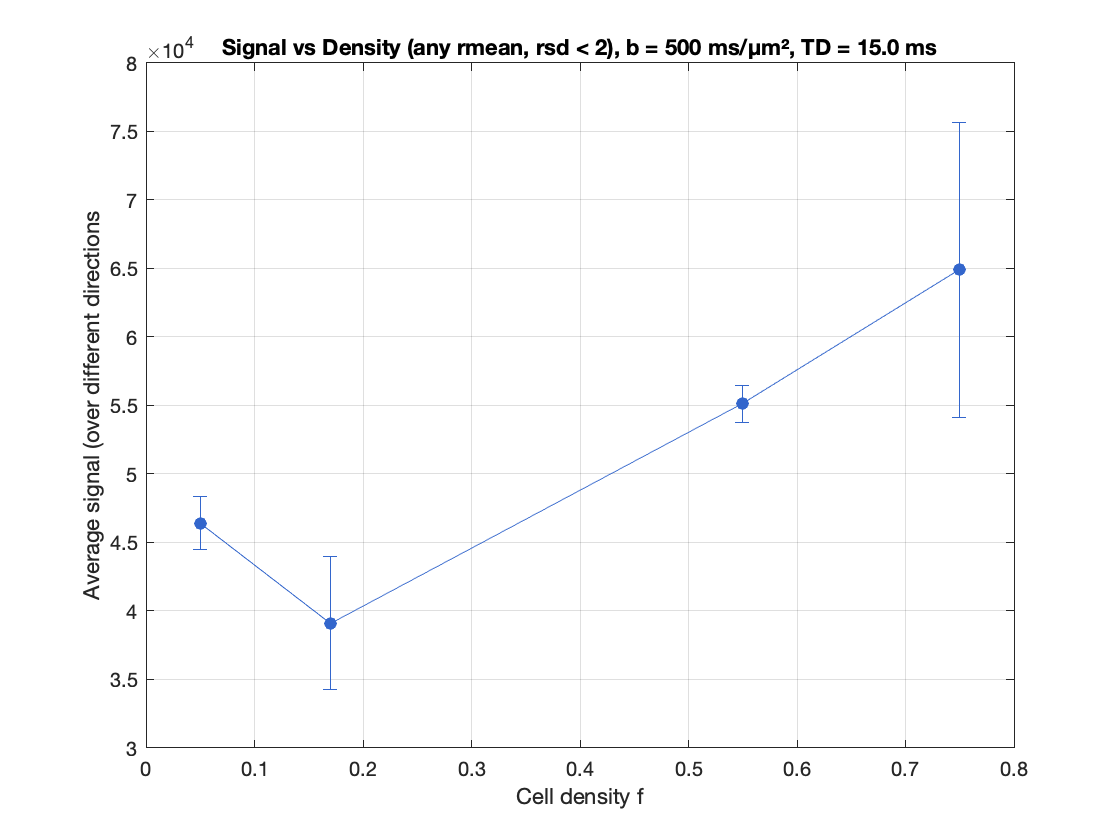

% Indexes
b_index = 3;
td_index = 1;

% Parameters extraction 
f_all     = params(:,1);  % cell density
rsd_all   = params(:,4);  % radius sd
Dex_all = params(:,2); 
signals   = squeeze(signals_4D(:, td_index, b_index, :));  
signals_avg = mean(signals, 2);  % mean over all directions

% Filter for rsd<2
filter_idx = rsd_all < 2;
f_all = f_all(filter_idx);
Dex_all = Dex_all(filter_idx);
signals_avg = signals_avg(filter_idx);

% Gather f values in intervals
f_bins = unique(round(f_all, 2));  % 0.01 step
f_mean = [];
s_mean = [];
s_std  = [];

for j = 1:numel(f_bins)
    fj = f_bins(j);
    idx = abs(f_all - fj) < 1e-3 & (Dex_all>=1.5) & (Dex_all<2.5);
    if sum(idx) < 2, continue; end
    f_mean(end+1) = fj;
    s_mean(end+1) = mean(signals_avg(idx));
    s_std(end+1)  = std(signals_avg(idx));
end

% Plot
figure;
errorbar(f_mean, s_mean, s_std, 'o-', ...
    'Color', [0.2 0.4 0.8], ...
    'MarkerFaceColor', [0.2 0.4 0.8]);

xlabel('Cell density f');
ylabel('Average signal (over different directions');
title(sprintf('Signal vs Density (any rmean, rsd < 2), b = %.0f ms/µm², TD = %.1f ms', ...
    sequence.bval(b_index)*1000, sequence.TD(td_index)));

grid on;

## 3D signal plot depending on cell density and extracellular diffusivity

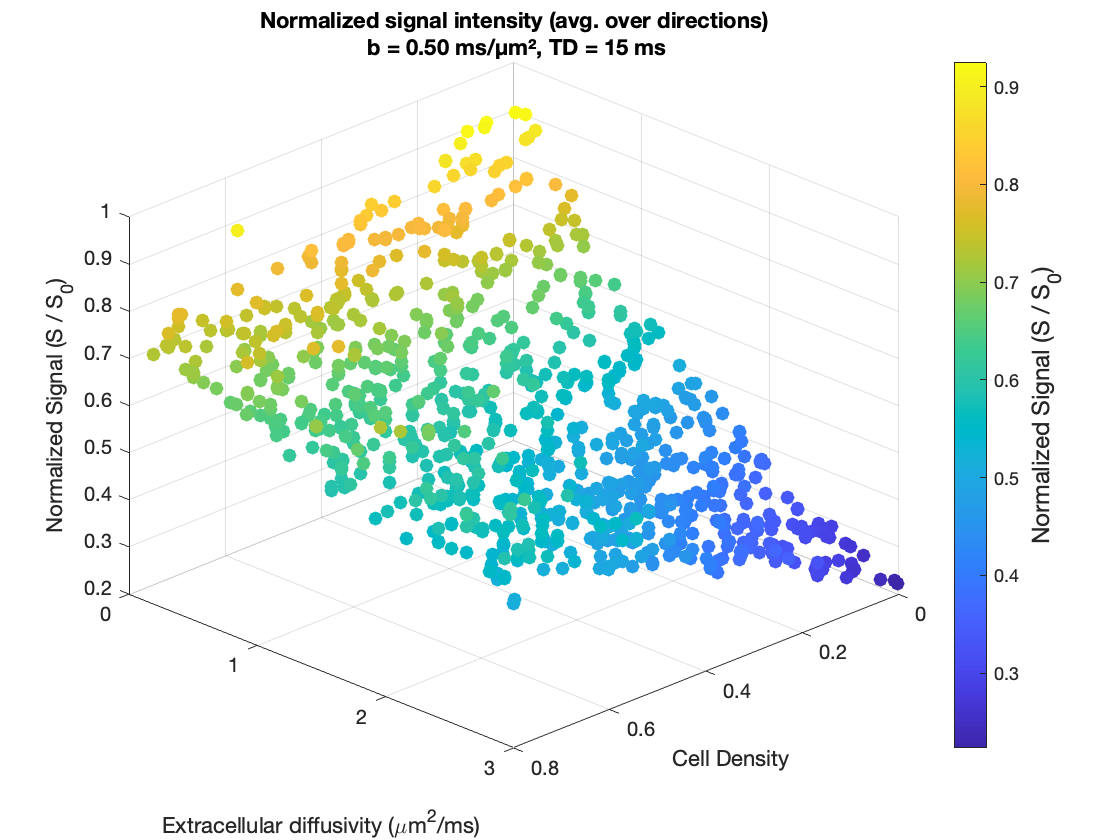

% Indexes of bvalue and diffusion time
b0_index = 1;
b_index = 3;
td_index = 1;

% Parameters extraction
f_all     = params(:,1);
Dex_all   = params(:,2);
rmean_all = params(:,3);
rsd_all   = params(:,4);

% Filter : RSD < 10
valid_idx = rsd_all < 10;

f_all     = f_all(valid_idx);
Dex_all   = Dex_all(valid_idx);
sig_temp  = squeeze(signals_4D(valid_idx, td_index, b_index, :));  % [N × n_bvecs]
S0_temp   = squeeze(signals_4D(valid_idx, td_index, b0_index, :)); %for normalization

% Average over directions
sig_avg = mean(sig_temp, 2);  % [N × 1]
S0_avg  = mean(S0_temp, 2);

% Normalize
sig_norm = sig_avg ./ S0_avg;

% Create figure
figure;
scatter3(f_all, Dex_all, sig_norm, 50, sig_norm, 'filled');
xlabel('Cell Density');
ylabel('Extracellular diffusivity (\mum^2/ms)');
zlabel('Normalized Signal (S / S_0)');

% Add real b-value and TD in title
b_value_real = bval(b_index);
TD_real = TD(td_index);
title(sprintf('Normalized signal intensity (avg. over directions)\n b = %.2f ms/µm², TD = %d ms', b_value_real, TD_real));

% Caption
cb = colorbar;
cb.Label.String = 'Normalized Signal (S / S_0)';
cb.Label.FontSize = 12;

view(135, 30);
grid on;

% Save figure in "Figures" folder
if ~exist('Figures', 'dir')
    mkdir('Figures');
end
filename = sprintf('Figures/scatter3_b%d_TD%d.png', b_value_real*100, TD_real); 
saveas(gcf, filename);

## 3D plot signal intensity depending on cell mean radius and standard deviation 

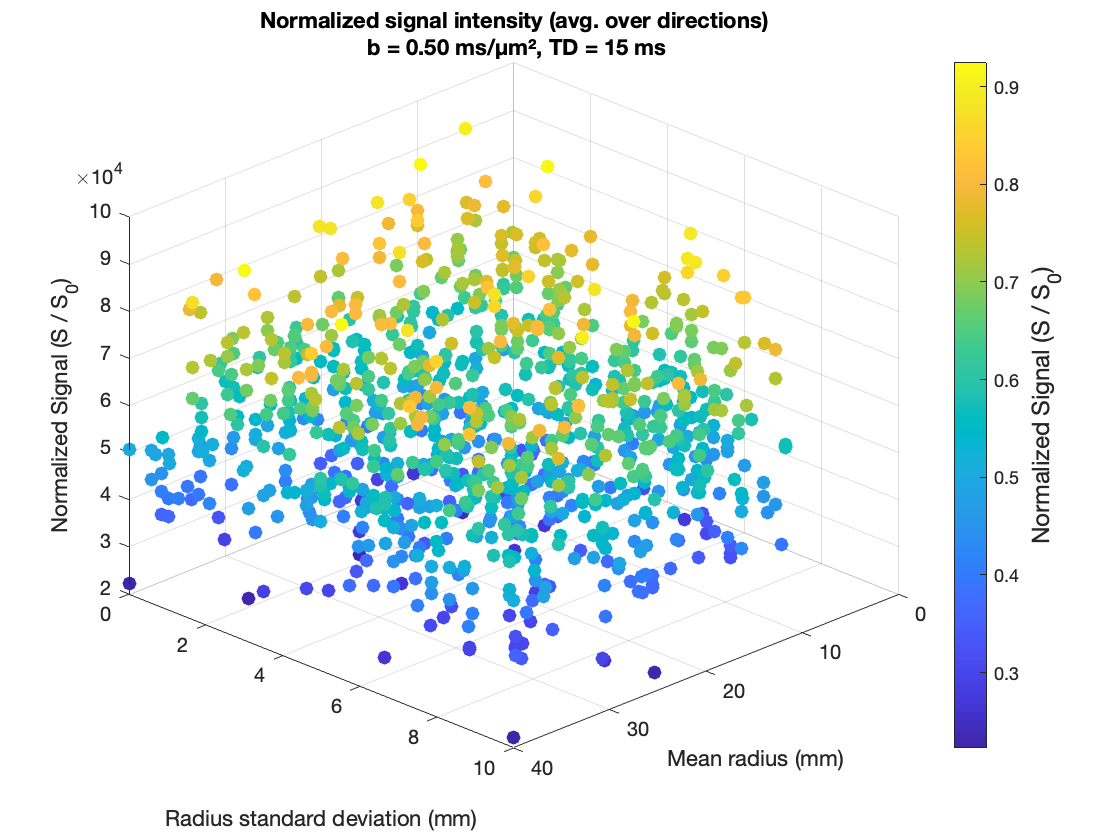

% Indexes
b0_index = 1;
b_index = 3;
td_index = 1;

% Parameters extraction
f_all     = params(:,1);
Dex_all   = params(:,2);
rmean_all = params(:,3);
rsd_all   = params(:,4);

% Filter : RSD < 2
valid_idx = f_all < 10; 

rmean_all = rmean_all(valid_idx);
rsd_all   = rsd_all(valid_idx);
sig_temp  = squeeze(signals_4D(valid_idx, td_index, b_index, :));  % [N × n_bvecs]
S0_temp   = squeeze(signals_4D(valid_idx, td_index, b0_index, :)); %for normalization

% Average over directions
sig_avg = mean(sig_temp, 2);  % [N × 1]
S0_avg  = mean(S0_temp, 2);

% Normalize
sig_norm = sig_avg ./ S0_avg;

%bvalue and TD
b_value_real = bval(b_index);
TD_real = TD(td_index);

% Scatter plot
figure;
scatter3(rmean_all, rsd_all, sig_avg, 50, sig_norm, 'filled');
xlabel('Mean radius (mm)');
ylabel('Radius standard deviation (mm)');
zlabel('Normalized Signal (S / S_0)');
title(sprintf('Normalized signal intensity (avg. over directions)\n b = %.2f ms/µm², TD = %d ms', b_value_real, TD_real));

% Caption
cb = colorbar;
cb.Label.String = 'Normalized Signal (S / S_0)';
cb.Label.FontSize = 12;

view(135, 30);
grid on;

## 3D plot of signal depending on bvalues and diffusion times

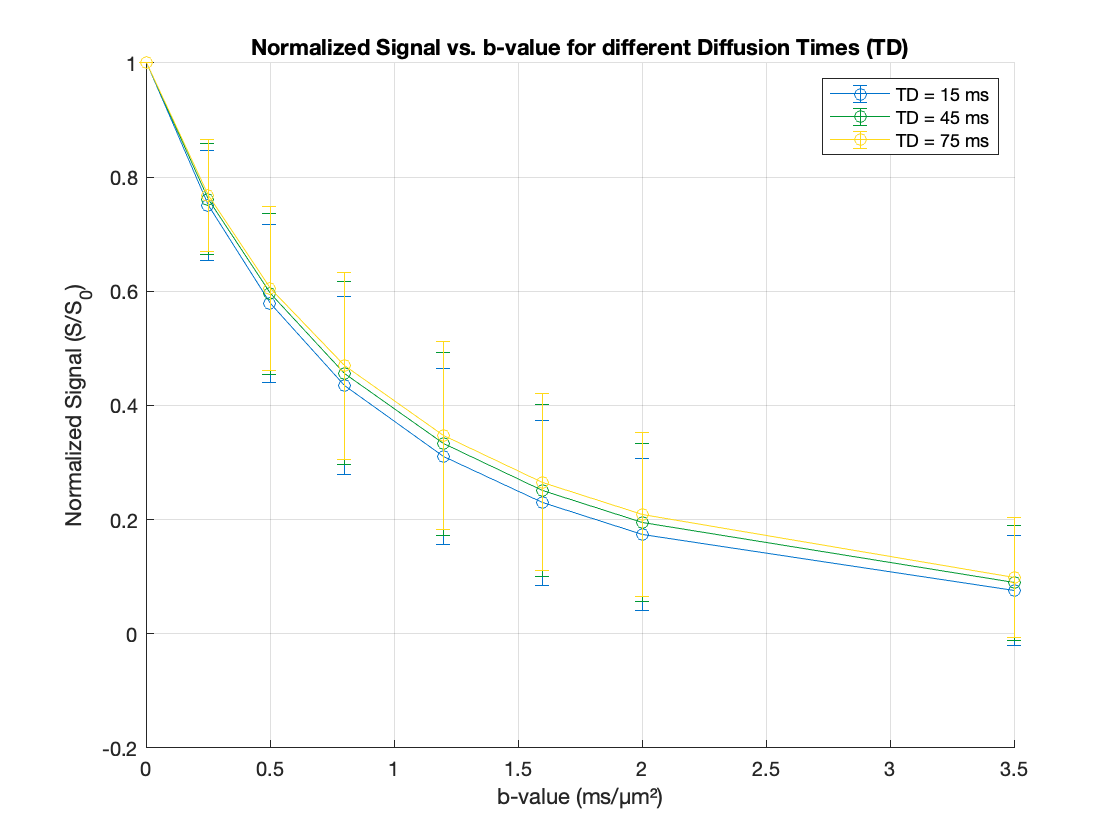

% Extract bvalue and diffusion time 
bvals = sequence.bval;     % [n_bval × 1]
TDs   = sequence.TD;       % [n_del × 1]

% Filter simulations (<10 means all rsd)
valid_idx = rsd_all < 10;
signals_valid = signals_4D(valid_idx, :, :, :);  % [N × n_del × n_bval × n_bvec]

% Average over directions
signals_avg_bvec = squeeze(mean(signals_valid, 4));  % [N × n_del × n_bval]

% Average over N combinations
signals_mean = squeeze(mean(signals_avg_bvec, 1));  % [n_del × n_bval]
signals_std  = squeeze(std(signals_avg_bvec, 0, 1)); % [n_del × n_bval]

% --- Normalization by b=0 (assume first bval is 0) ---
S0 = signals_mean(:, 1);   % [n_del × 1] baseline (b=0)
signals_mean_norm = signals_mean ./ S0;   % broadcasting over columns
signals_std_norm  = signals_std ./ S0;    % same normalization for std

% Plot normalized signals
figure; hold on;
my_colors = [ ...
    0 0.45 0.8;   % blue
    0 0.6 0.2;    % green
    1.0 0.85 0.1  % yellow
];

for i = 1:numel(TDs)
    errorbar(bvals, signals_mean_norm(i,:), signals_std_norm(i,:), ...
        '-o', 'Color', my_colors(i,:), ...
        'DisplayName', sprintf('TD = %.0f ms', TDs(i)));
end

xlabel('b-value (ms/µm²)');
ylabel('Normalized Signal (S/S_0)');
title('Normalized Signal vs. b-value for different Diffusion Times (TD)');
legend('Location', 'northeast');
grid on;

% Save figure in "Figures" folder
if ~exist('Figures', 'dir')
    mkdir('Figures');
end
filename = sprintf('Figures/sig_exp_decay.png'); 
saveas(gcf, filename);

## Mutlivariate analysis

% -----------------------------
% Préparation des données
% -----------------------------
[n_sim, nDel, nBval, nBvec] = size(signals_4D);

X = [];  % Features: f, Dex, rmean, rsd, bval, TD
y = [];  % Signal moyen

for td_idx = 1:nDel
    for b_idx = 1:nBval
        sig_avg = squeeze(mean(signals_4D(:, td_idx, b_idx, :), 4));  % [n_sim × 1]

        X_temp = [params(:,1:4), ...  % On ignore kappa (5e colonne)
                  repmat(sequence.bval(b_idx), n_sim, 1), ...
                  repmat(sequence.TD(td_idx), n_sim, 1)];

        X = [X; X_temp];
        y = [y; sig_avg];
    end
end

% Noms des paramètres
param_names = {'f', 'Dex', 'rmean', 'rsd', 'bval', 'TD'};

% -----------------------------
% Normalisation (optionnelle)
% -----------------------------
y_norm = normalize(y, 'range');  % Min-max scaling [0,1]
data_table = array2table([X y_norm], 'VariableNames', [param_names, {'Signal'}]);

% -----------------------------
% Matrice de corrélation
% -----------------------------
corr_matrix = corr(table2array(data_table));

disp('Correlation Matrix:');

Correlation Matrix:


disp(array2table(corr_matrix, 'VariableNames', [param_names, {'Signal'}], ...
                 'RowNames', [param_names, {'Signal'}]));

                  f             Dex          rmean          rsd           bval            TD          Signal  
              __________    ___________    __________    __________    ___________    ___________    _________

    f                  1      0.0014909     -0.015066     -0.007307     4.4813e-18     1.3074e-18     0.097174
    Dex        0.0014909              1     -0.001335    -0.0045019     9.5481e-19    -1.6606e-18      -0.2965
    rmean      -0.015066      -0.001335             1      0.068623     3.6265e-18     -4.022e-19    -0.053908
    rsd        -0.007307     -0.0045019      0.068623             1              0     3.0275e-18    -0.027276
    bval  

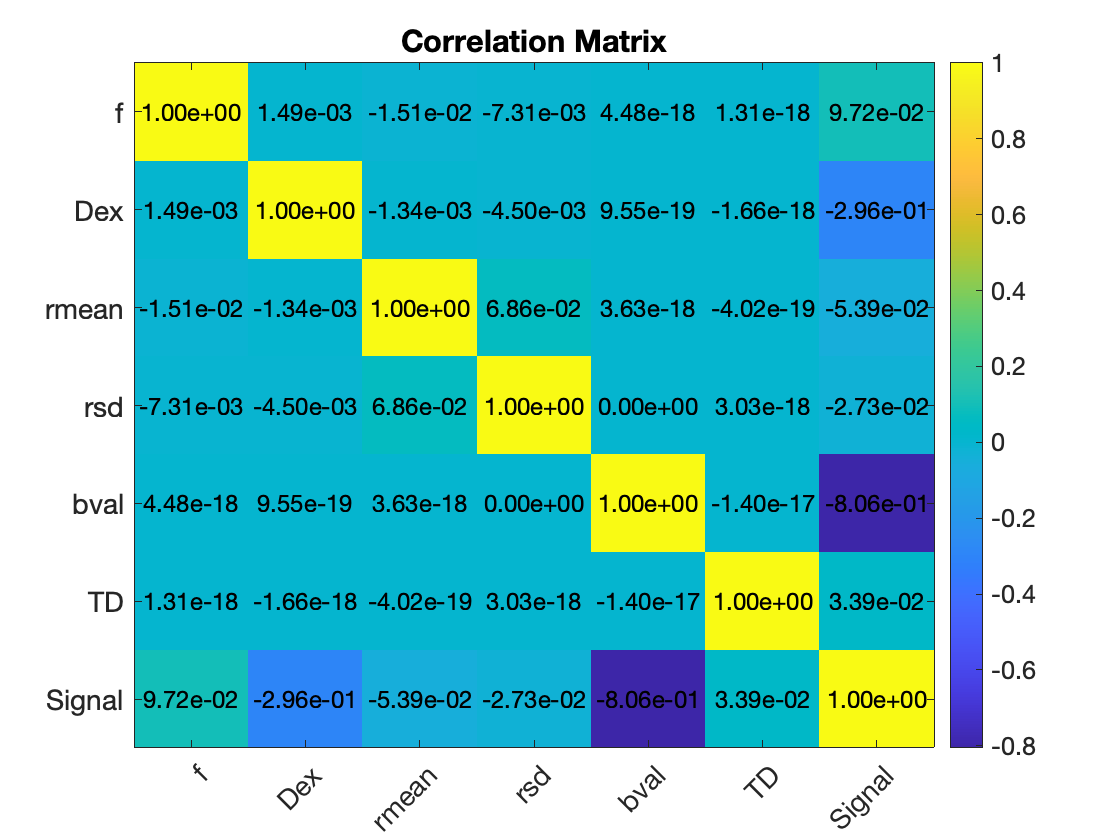


% -----------------------------
% Heatmap avec labels formatés
% -----------------------------
figure;
imagesc(corr_matrix);
colormap(parula);
colorbar;
title('Correlation Matrix');

xticks(1:numel(param_names)+1);
yticks(1:numel(param_names)+1);
xticklabels([param_names, {'Signal'}]);
yticklabels([param_names, {'Signal'}]);
set(gca, 'FontSize', 14, 'XTickLabelRotation', 45);

% Ajouter les valeurs dans la matrice en notation scientifique
[nRows, nCols] = size(corr_matrix);
for i = 1:nRows
    for j = 1:nCols
        text(j, i, sprintf('%.2e', corr_matrix(i,j)), ...
            'HorizontalAlignment', 'center', 'Color', 'k', 'FontSize', 12);
    end
end

% Save figure in "Figures" folder
if ~exist('Figures', 'dir')
    mkdir('Figures');
end
filename = sprintf('Figures/Corrmatrix.png'); 
saveas(gcf, filename);

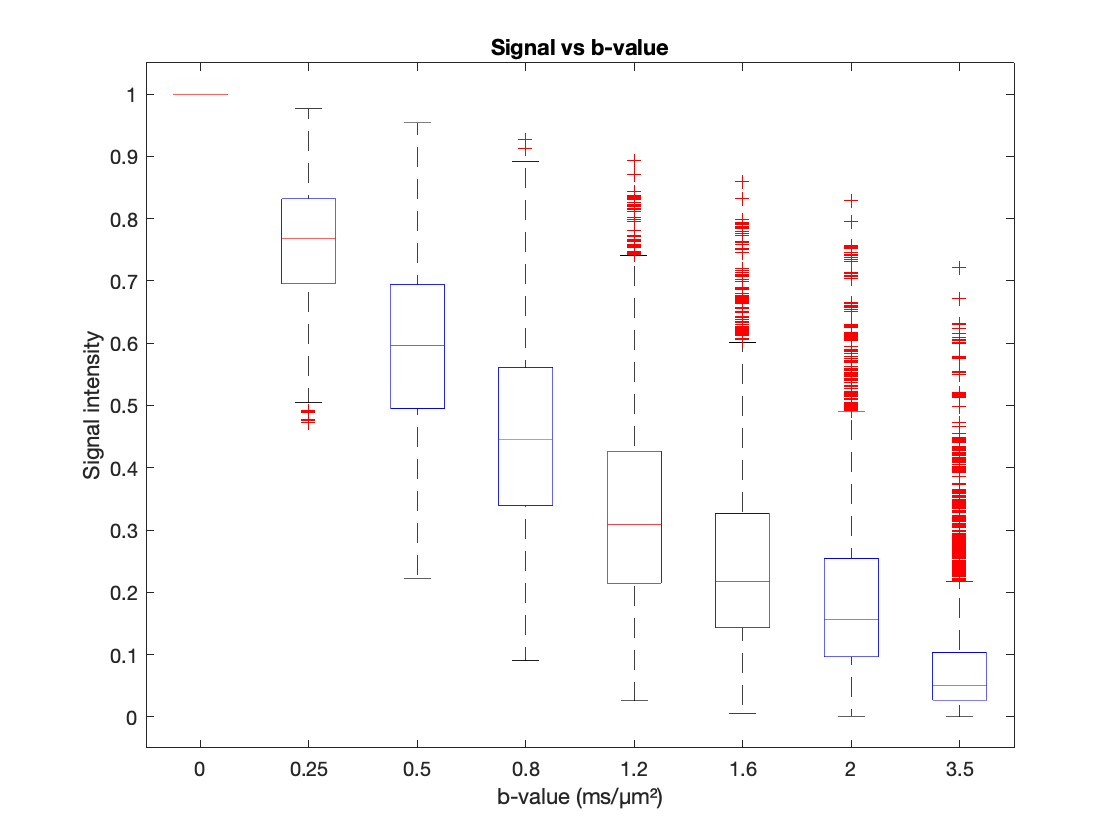


% -----------------------------
% Boxplots
% -----------------------------
figure;
boxplot(y_norm, X(:,5));  % bval
xlabel('b-value (ms/µm²)');
ylabel('Signal intensity');
title('Signal vs b-value');

% Save figure in "Figures" folder
if ~exist('Figures', 'dir')
    mkdir('Figures');
end
filename = sprintf('Figures/Boxplot_signal.png'); 
saveas(gcf, filename);

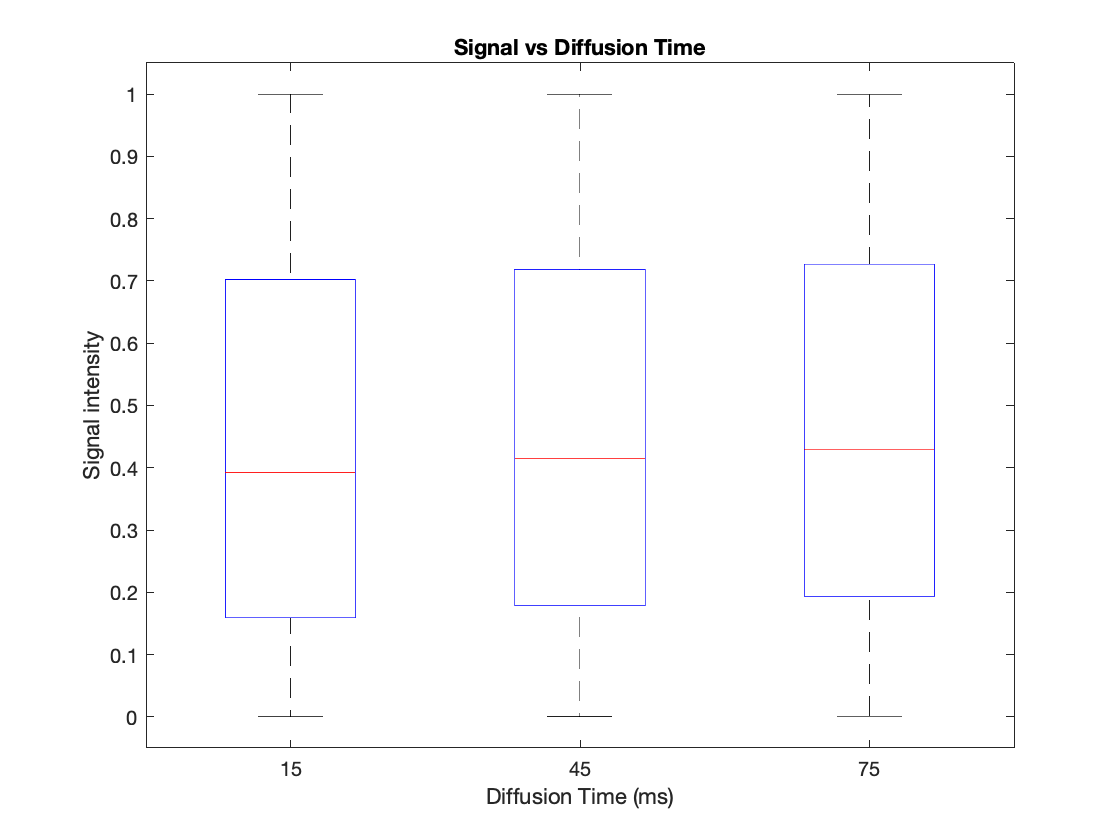


figure;
boxplot(y_norm, X(:,6));  % TD
xlabel('Diffusion Time (ms)');
ylabel('Signal intensity');
title('Signal vs Diffusion Time');

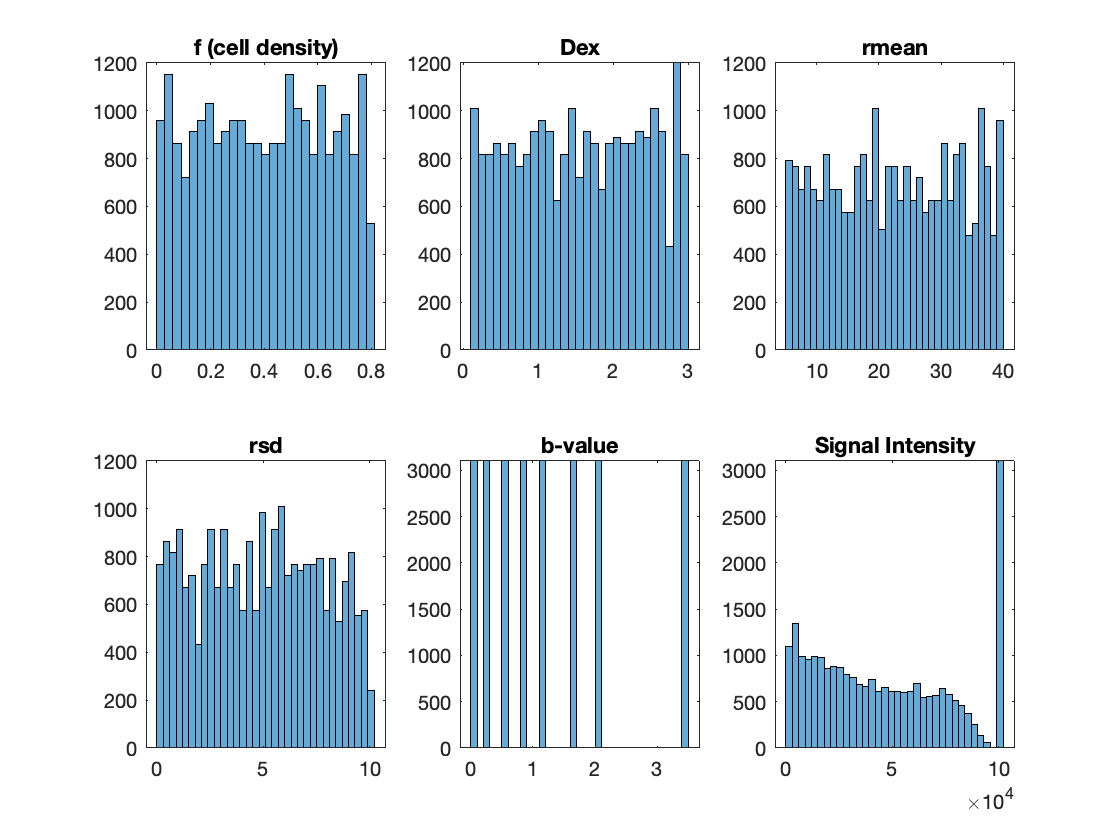


% -----------------------------
% Histogrammes
% -----------------------------
figure;
subplot(2,3,1); histogram(X(:,1)); title('f (cell density)');
subplot(2,3,2); histogram(X(:,2)); title('Dex');
subplot(2,3,3); histogram(X(:,3)); title('rmean');
subplot(2,3,4); histogram(X(:,4)); title('rsd');
subplot(2,3,5); histogram(X(:,5)); title('b-value');
subplot(2,3,6); histogram(y);       title('Signal Intensity');

## Searching function

%%%